# Single Neuron Analysis

clc;
clear;
close all;

### **Load Data**

load('data_Flint_2012_e1.mat')
data

data = 다음 필드를 포함한 175×1 struct 배열:
    HandPos
    HandVel
    HandAcc
    Time
    Neuron
    class
    cueOnset
    movementOnset
    movementMax
    movementOffset


### Get information for class and time

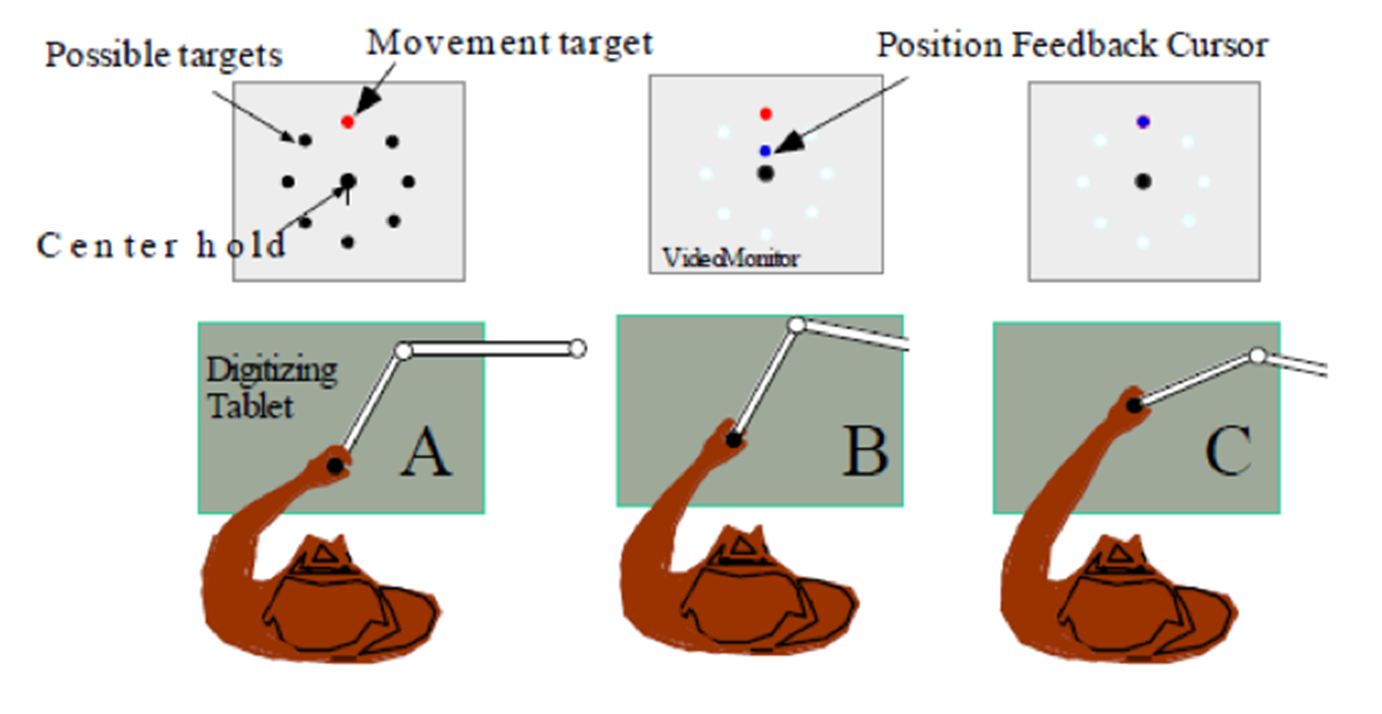

Directions

idx_class = [data.class];
class_list = unique(idx_class);
n_class = length(class_list)

n_class = 8

The trial time differs for each trial. The behavior data is recorded every 0.01 ms.

trial_time = {data.Time};
move_onset = [data.movementOnset];

### **Data Processing - get spike timing data**

Neural data include the **spike timing** and LFP data. We will use the spike timing for analysis

% Generate Trial x Neuron spike_trian_matrix
n_trials = length(data)

n_trials = 175

% The dataset consists of 196 neurons
n_neuron = length(data(1).Neuron)

n_neuron = 196

spike_data = cell(n_trials,n_neuron); 
for i = 1:n_trials
    for j = 1:n_neuron
        spike_data{i,j} = data(i).Neuron(j).Spike;
    end
end

#### Select neuron (example)

% 1 15 16 17 19 65
idx_neuron = 15;

**Generate Raster Plot**

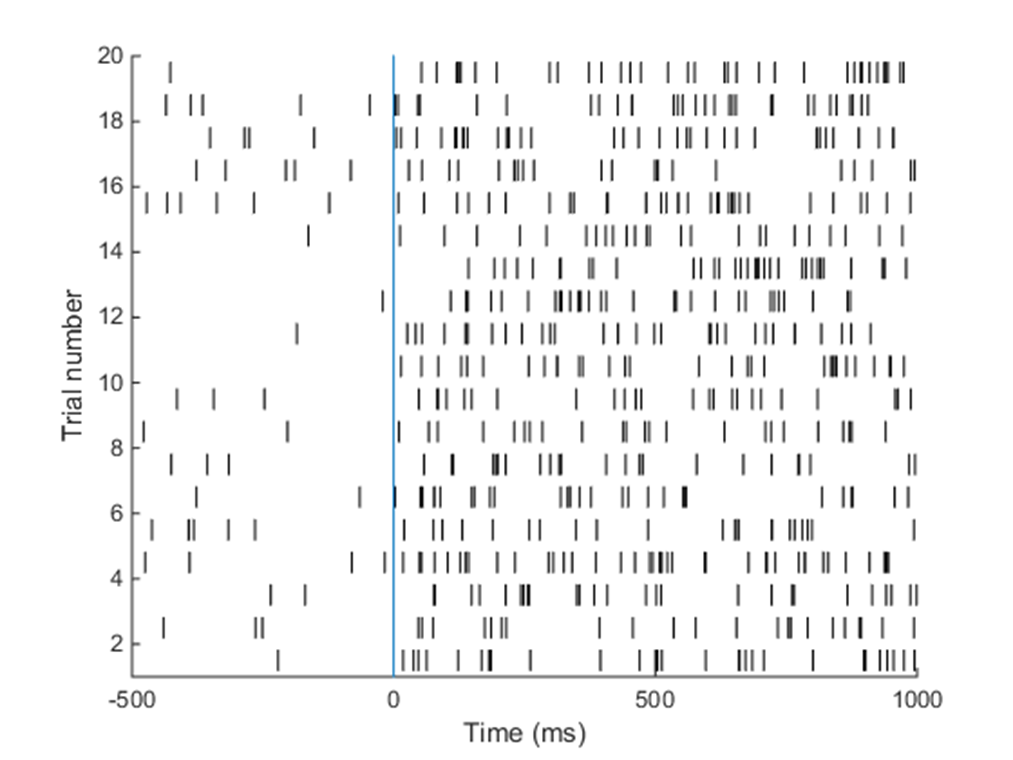

spike_timing = {};
for iclass = 1: n_class
    class_idx = idx_class == class_list(iclass);
    one_class_num_trial = length(find(class_idx));

    one_class_onset_idx = move_onset(class_idx);
    one_class_trial_time = trial_time(class_idx);
    one_class_a_spike = spike_data(class_idx, idx_neuron);

    for jtrial = 1: one_class_num_trial
        one_trial_spike = one_class_a_spike{jtrial};
        trial_onset_time = one_class_trial_time{jtrial}(one_class_onset_idx(jtrial));


#### `!!!Fill the blank!!!`

        % Time-locked to event onset
        spike_timing{iclass,jtrial} = one_trial_spike - trial_onset_time;
    end
end

**Plot Raster Plot**

-0.5 ~ 0.5 sec spike timing from movement onset

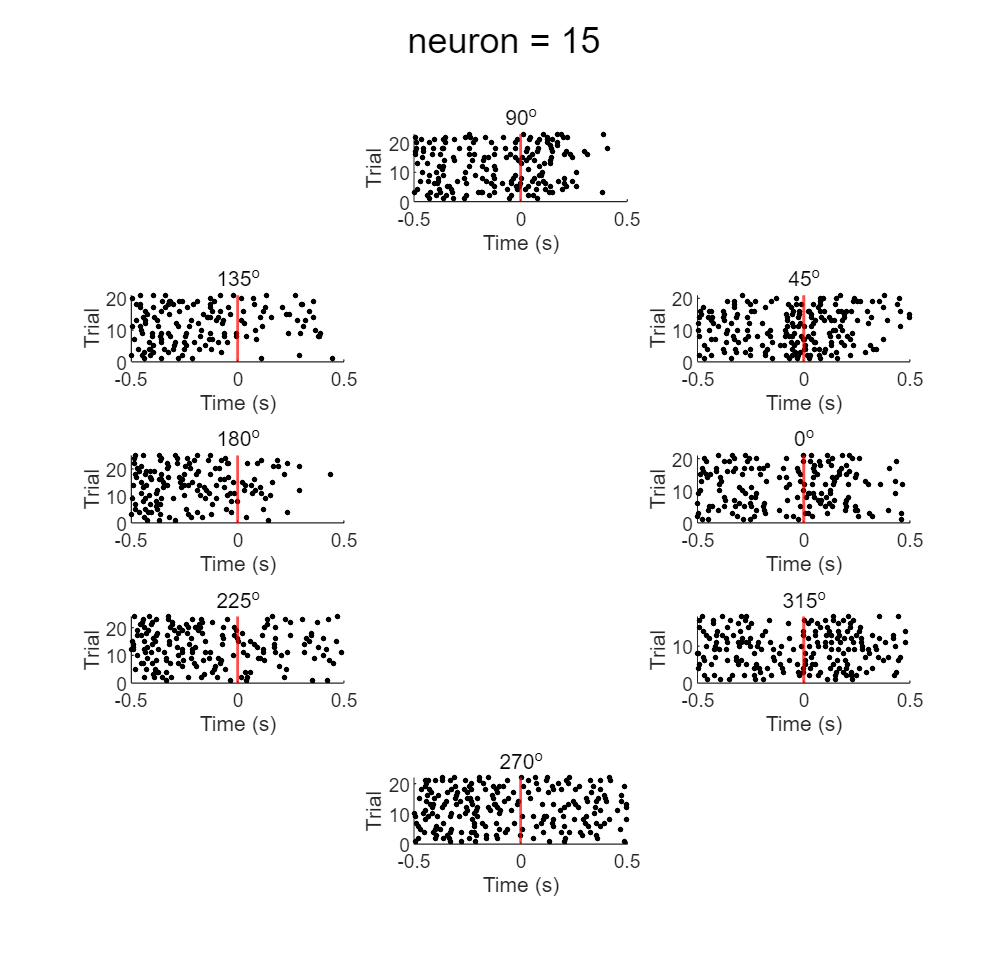

% For subplot
fig_pos = [9 6 2 4 7 10 14 12];
dir_list = 0:45:315; % degree
[n_class, n_trials] = size( spike_timing );

figure('Position',[560 200 560 540])
for iclass = 1: n_class
    subplot(5,3,fig_pos(iclass))
    Y = 0;
    for itrial = 1: n_trials
        one_spike_timing = spike_timing{iclass, itrial};
        if isempty(one_spike_timing)
            continue;
        end

        Y = Y + 1;
        sc = scatter(one_spike_timing, repmat( Y, size(one_spike_timing)), 5, 'k', 'filled' ); hold on;
    end
    xline(0, 'r','LineWidth',1.2); % line for onset
    % set options
    xlabel('Time (s)'); ylabel('Trial');
    xlim([-.5 .5]); ylim([0 Y]);
    title([num2str(dir_list(iclass)) '^o']);
end
sgtitle(['neuron = ' num2str(idx_neuron)]);

### **Peri-Stimulus Time Histogram (PSTH)**

-0.5 ~ 0.5 sec PSTH from movement onset

% Set options
fs = 1000;
time = -.5:1/fs:.5; time(1) =[];
n_timesteps = length(time);

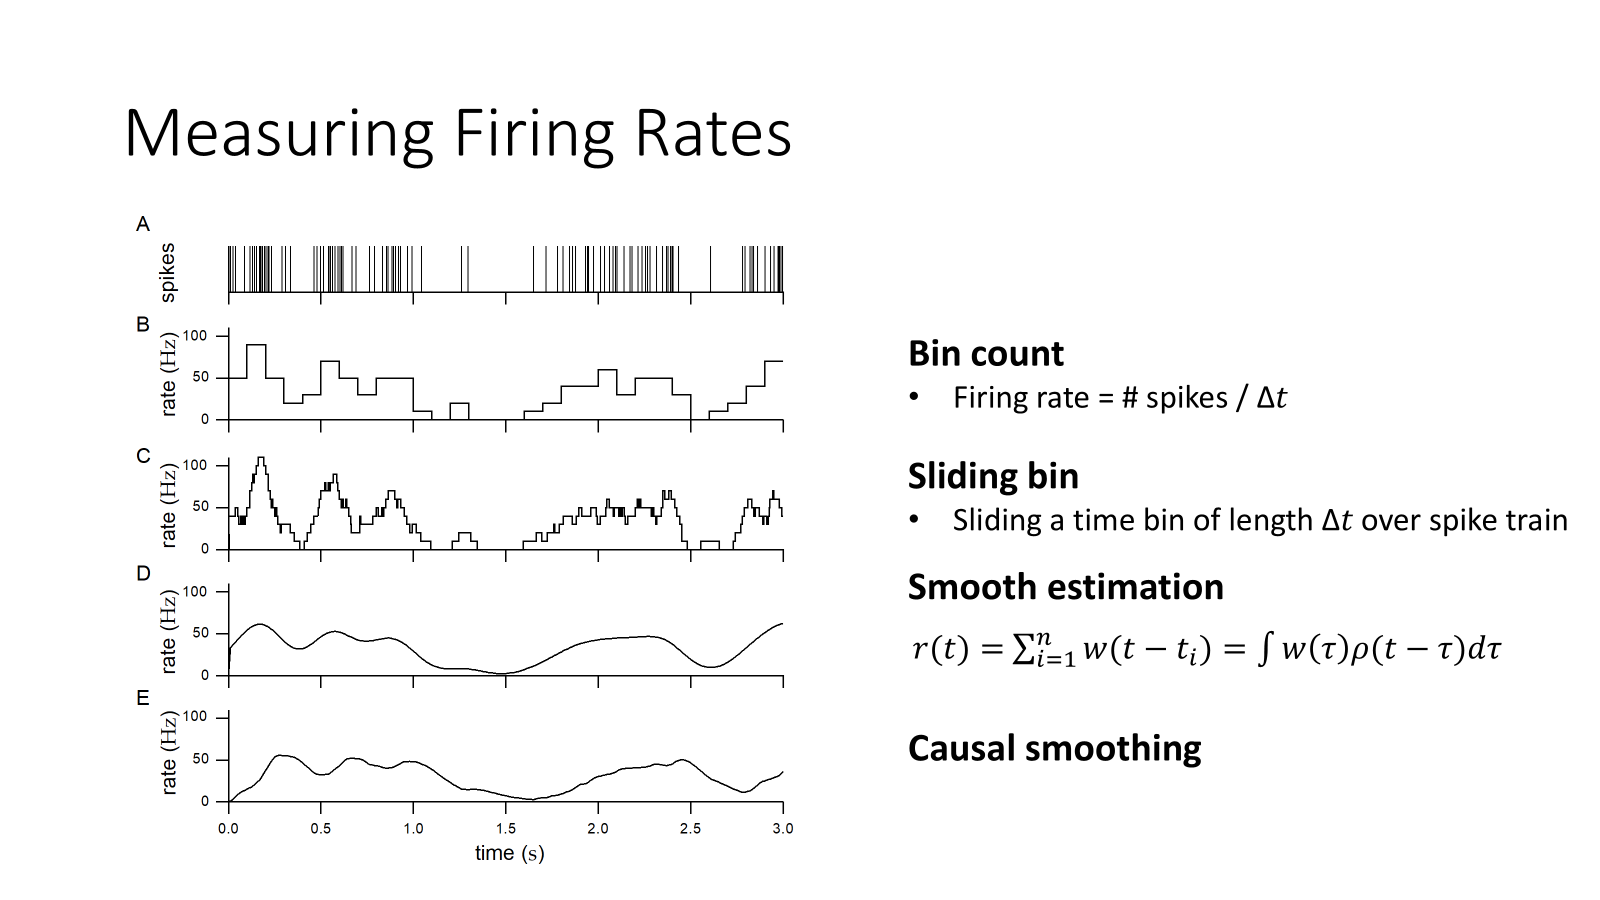

% Set bin of length time
bin_size = 0.1; % ms
win = time' + [-bin_size bin_size]./2;

#### Get Firing rate

[n_class, n_trials] = size( spike_timing );

firing_rate = nan(n_class, n_trials,n_timesteps);
for iclass = 1: n_class
    for itrial = 1: n_trials
        one_spike_timing = spike_timing{iclass, itrial};
        if isempty(one_spike_timing)
            continue;
        end
        for itimestep = 1: n_timesteps
            spiking_count = find( one_spike_timing>win(itimestep,1) & one_spike_timing<win(itimestep,2));
            num_spike = length( spiking_count );

#### `!!!Fill the blank!!!`

            % get firing rate
            firing_rate(iclass, itrial, itimestep) = num_spike ./ bin_size;
        end
    end
end

avg_firing_rate = squeeze( mean(firing_rate, 2, 'omitnan') );

#### Plotting Peri-Stimulus Time Histogram (PSTH)

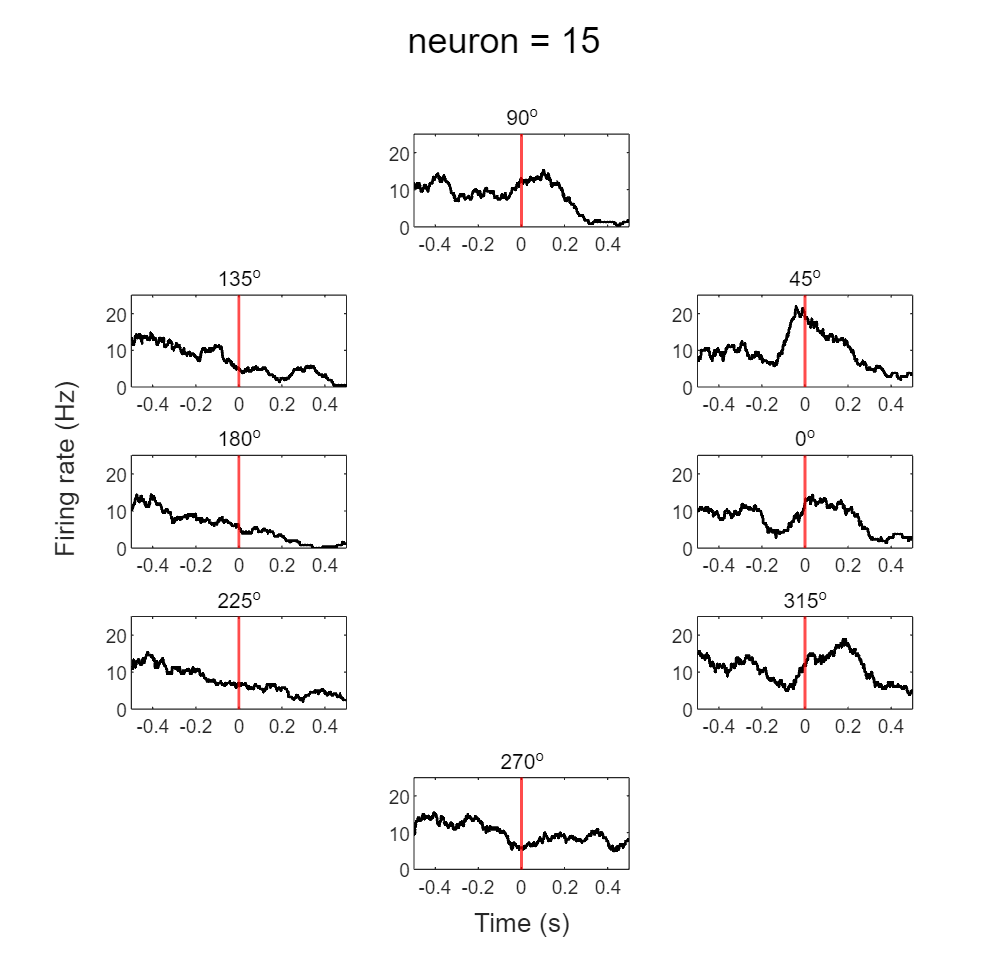

figure('Position',[560 200 560 540])
for iclass = 1: n_class
    subplot(5,3,fig_pos(iclass))
    plot(time,avg_firing_rate(iclass,:),'k','LineWidth',1.2); hold on;
    xline(0, 'r','LineWidth',1.2);

    title([num2str(dir_list(iclass)) '^o']);

    xlim([min(time), max(time)])
    ylim([0 25])
end
sgtitle(['neuron = ' num2str(idx_neuron)]);

ax = axes(gcf,'Visible', 'off');
ax.XLabel.Visible = 'on';
ax.YLabel.Visible = 'on';
xlabel('Time (s)'); ylabel('Firing rate (Hz)');